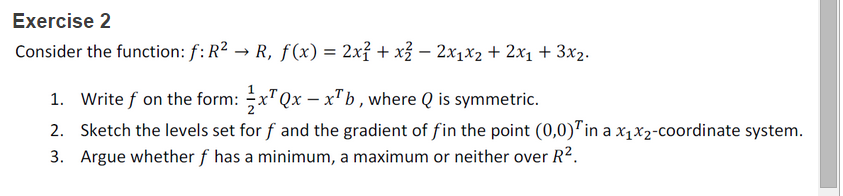

clear
syms x1 x2
Q = [2, -1;
    -1, 1];
Q = Q+Q'

Q =      4    -2
    -2     2



b = -[2;3;]

b =     -2
    -3



fq = @(x1,x2) 1/2 * [x1 x2]*Q*[x1;x2] - [x1 x2]*b

fq = function_handle with value:
    @(x1,x2)1/2*[x1,x2]*Q*[x1;x2]-[x1,x2]*b





% LEVEL SET
zhandle = fcontour(fq)

zhandle =   FunctionContour with properties:

     Function: @(x1,x2)1/2*[x1,x2]*Q*[x1;x2]-[x1,x2]*b
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [0 20 40 60 80 100 120]

  Show all properties


hold on
zhandle.LevelList = [1,2,3];
xlabel x1
ylabel x2
title(func2str(fq))
grid on
zhandle.YRange = [-10,10];
zhandle.XRange = [-10,10];
axis equal

g1 = diff(fq,x1)

$$g1 = 4\,x_{1}-2\,x_{2}+2$$

g2 = diff(fq,x2)

$$g2 = 2\,x_{2}-2\,x_{1}+3$$

gradient= [g1 g2]

$$gradient = \left(\begin{array}{cc} 4\,x_{1}-2\,x_{2}+2 & 2\,x_{2}-2\,x_{1}+3 \end{array}\right)$$

gf= matlabFunction(gradient);
gf(0,0)

ans =      2     3


pl = plot([0,2],[0,3],'red')

pl =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 2]
              YData: [0 3]
              ZData: [1×0 double]

  Show all properties


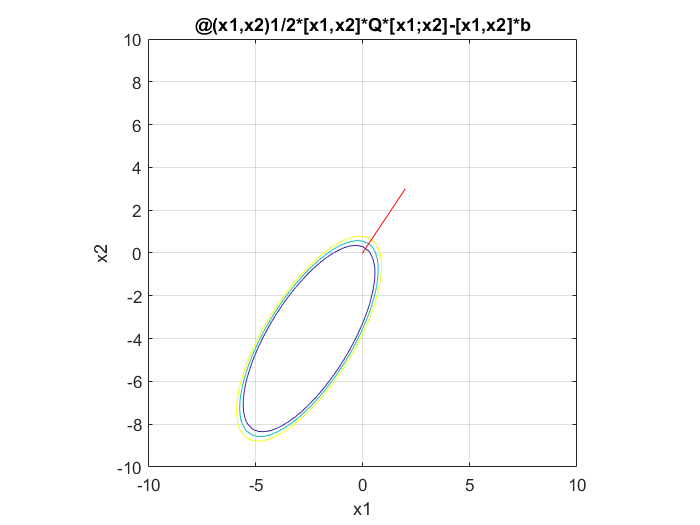

hold off

## c)

For *f* to have a minimum, the Hessian must be positive definite or positive semidefinite.

For *f *to have a maximum, the Hessian must be negative definite or negative semidefinite.

The Hessian is equal to the Q matrix. The eigenvalues of the Hessian are therefore equal to the eigenvalues of Q:


$$\lambda =\left\lbrack \begin{array}{c}
2\\
6
\end{array}\right\rbrack$$


eigen_values = eig(Q)

eigen_values =     0.7639
    5.2361


The eigenvalues are all positive, which means that the Hessian is **positive** **definite**. This means that the function has a minimum in $R^2$.

## Exercise 3

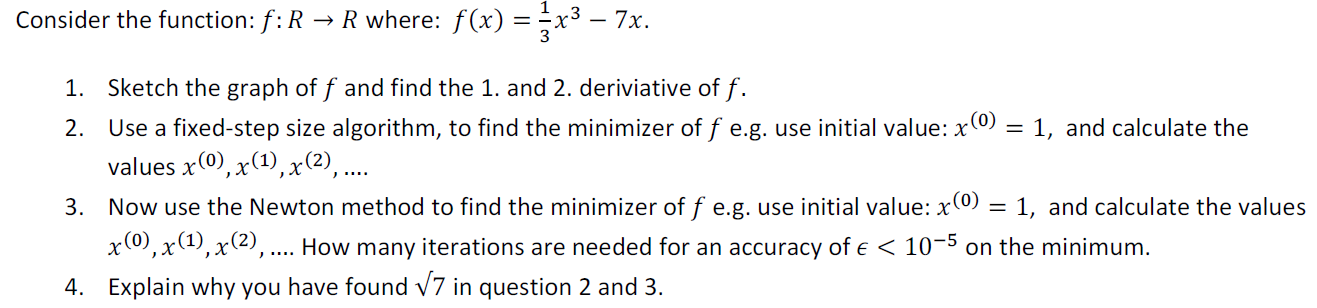


$$f\left(x\right)=\frac{1}{3}x^3 -7x$$


clear

syms x
f = @(x) 1/3*x^3-7*x

f = function_handle with value:
    @(x)1/3*x^3-7*x


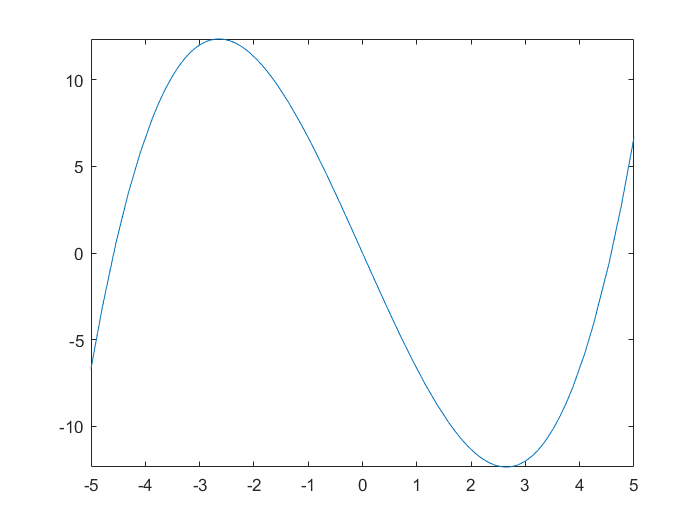

fplot(f)

%1. derivate
gradient = diff(f,x)

$$gradient = x^{2}-7$$

gradient = matlabFunction(gradient);
%2. derivate
hessian = diff(f,x,x)

$$hessian = 2\,x$$


eig_max = eig(hessian) % returns eigenvector with largest magnitude

$$eig\_max = 2\,x$$

syms a
range = 0 < a < (2/eig_max)

$$range = \left(0<a\right)<\frac{1}{x}$$

x0 = 1;
alpha = 0.05

alpha = 0.0500

N = 40; % iterations
x0 = 1;
x = zeros(N,1);
x(1) = x0;

for i=1:N
    gradient(x(i));
    x(i+1) = x(i)-alpha*gradient(x(i));
end
x

x =     1.0000
    1.3000
    1.5655
    1.7930
    1.9822
    2.1358
    2.2577
    2.3528
    2.4260
    2.4818




%Newton with accuracy
hessian = matlabFunction(hessian)

hessian = function_handle with value:
    @(x)x.*2.0


x0 = 1;
N = 100 % iterations

N = 100

x = zeros(1,N)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x(1,:) = x0;
accuracy = 10^-5;

for i=1:N
    g = gradient(x(i,1));
    x(i+1,:) = x(i,:)'-hessian(x(i,1))^-1*g;
    e = abs(x(i+1)-x(i));
    if e < accuracy
        break
    end
end
x

x =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4

## d)

Both algorithms converge towards the minimum $x=\sqrt{7}$. Both algorithms converge because the starting point is placed in a point where the gradient is negative and move towards the minimum.

If the starting point had been placed on the other side of the minimum, the algorithm would not have converged towards the minimum.

## Exercise 4

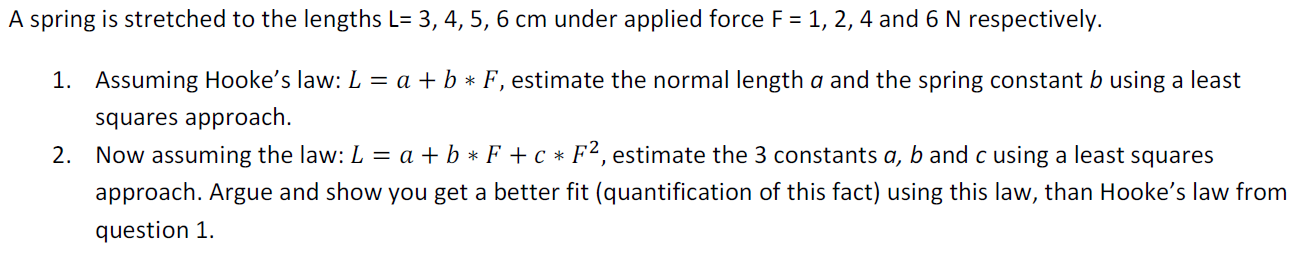

The measurements are:


$$L=3,4,5,6$$



$$F=1,2,4,6$$


L1 = 3; L2 = 4; L3 = 5; L4 = 6;
L = [L1 L2 L3 L4];
F1 = 1; F2 = 2; F3 = 4; F4 = 6;
F = [F1 F2 F3 F4];


This system of equations can then be written as:


$$A=\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2\\
1 & 4\\
1 & 6
\end{array}\right\rbrack ,\text{ }x=\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack ,\text{ }b=\left\lbrack \begin{array}{c}
3\\
4\\
5\\
6
\end{array}\right\rbrack$$


A = [1 F1; 1 F2; 1 F3; 1 F4]

A =      1     1
     1     2
     1     4
     1     6


b = [L1; L2; L3; L4]

b =      3
     4
     5
     6


The least-squares estimate for *a *and *b* is then given by:


$$x^\ast  =\left\lbrack \begin{array}{c}
a^\ast  \\
b^\ast  
\end{array}\right\rbrack ={\left(A^T A\right)}^{-1} A^T b=\left\lbrack \begin{array}{c}
2\ldotp 627\\
0\ldotp 576
\end{array}\right\rbrack$$


x = (A'*A)^-1*A'*b

x =     2.6271
    0.5763


a = x(1);
b = x(2);
L_est_a = @(F) a+b*F

L_est_a = function_handle with value:
    @(F)a+b*F


The residuals of the estimate:

L_a = [L_est_a(F(1)), L_est_a(F(2)), L_est_a(F(3)), L_est_a(F(4))]

L_a =     3.2034    3.7797    4.9322    6.0847


res_a = L_a-L

res_a =     0.2034   -0.2203   -0.0678    0.0847




%b
A = [1 F1 F1^2; 1 F2 F2^2; 1 F3 F3^3; 1 F4 F4^2]

A =      1     1     1
     1     2     4
     1     4    64
     1     6    36


b = [L1; L2; L3; L4]

b =      3
     4
     5
     6


x = (A'*A)^-1*A'*b

x =     2.6338
    0.5623
    0.0015


a = x(1);
b = x(2);
c = x(3);
L_est_b = @(F) a+b*F+c*F^2

L_est_b = function_handle with value:
    @(F)a+b*F+c*F^2


L_b = [L_est_b(F(1)), L_est_b(F(2)), L_est_b(F(3)), L_est_b(F(4))]

L_b =     3.1976    3.7643    4.9065    6.0606


res_b = L_b-L

res_b =     0.1976   -0.2357   -0.0935    0.0606


The residuals do not seem to support the fact that the definition of the law from b) is a better estimate than the law from a).

The measurements and estimates are plotted below. In the figure it is apparent that the two estimates are almost identical. However, the measurements also indicate that the model may not be linear, but that there are too fer measurements to say for sure. If the actual relation between F and L is not linear, the second order estimate will become more accurate compared to the linear fit as more measurements are added.

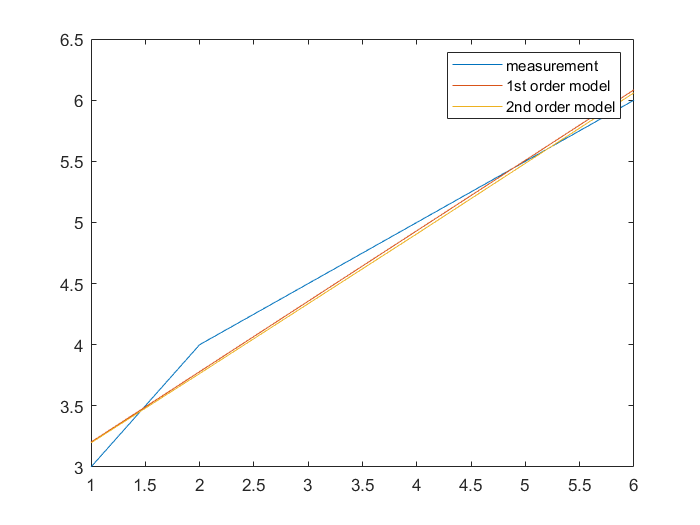

figure
plot(F,L,F,L_a,F,L_b)
legend('measurement','1st order model','2nd order model')